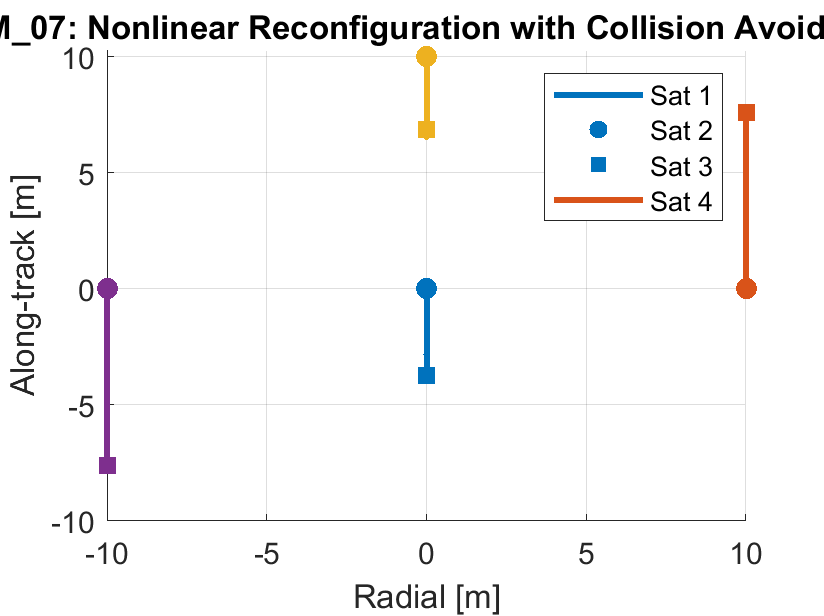

%% ========================================================================
%  SIM 07: Nonlinear Dynamics with Collision Avoidance (Keplerian)
%  --------------------------------------------------------------
%  - Demonstrates a nonlinear multi-satellite reconfiguration using
%    numerical propagation and a simplified collision avoidance approach.
%  - This scenario adds transitions away from CW to full nonlinear.
%
%  Author: Sabrina Nicacio
% ========================================================================

clear; clc;

%% Constants and Setup
mu = 3.986e14; % Earth's gravitational parameter [m^3/s^2]
Re = 6371e3;    % Earth's radius in meters
alt = 550e3;    % Orbital altitude of Starling [m]
r0 = Re + alt;  % Initial orbit radius [m]
T = 2*pi*sqrt(r0^3/mu); % Orbital period [s]
N = 4;          % Number of satellites
tf = 0.25 * T;  % Duration of reconfiguration [s]
dt = 10;        % Time step [s]
steps = floor(tf/dt);
r_min = 10;     % Min separation (avoidance radius) [m]

% Initial positions (in local LVLH frame)
x0 = [...
    0    0    0;
   10    0    0;
    0   10    0;
  -10    0    0];

% Desired final positions (new formation)
xf = [...
    0    10    0;
   10    10    0;
    0   -10    0;
  -10  -10    0];

%% Dynamics: Using ODEs to propagate motion
% 2-body propagation with thrust input modeled

% Initialize storage
X = zeros(steps, 3, N);  % state history [time, xyz, sat]
U = zeros(steps, 3, N);  % thrust profile
mass = 10;               % satellite mass [kg]
umax = 0.05;             % max acceleration [m/s^2]

for i = 1:N
    X(1,:,i) = x0(i,:);
end

% Simple proportional controller with repulsion
for k = 1:steps-1
    for i = 1:N
        pos = squeeze(X(k,:,i));
        error = xf(i,:) - pos;
        u = 0.001 * error;

        % Apply repulsive force from other satellites
        for j = 1:N
            if j ~= i
                d = pos - squeeze(X(k,:,j));
                dist = norm(d);
                if dist < r_min
                    u = u + (r_min - dist) * (d / dist); % push away
                end
            end
        end

        % Clip thrust
        if norm(u) > umax
            u = u / norm(u) * umax;
        end

        % Store and propagate
        U(k,:,i) = u;
        X(k+1,:,i) = pos + dt * u; % simplistic Euler integration
    end
end

%% Plot Results
figure;
hold on; grid on;
colors = lines(N);
for i = 1:N
    plot(X(:,1,i), X(:,2,i), 'Color', colors(i,:), 'LineWidth', 2);
    scatter(X(1,1,i), X(1,2,i), 50, colors(i,:), 'filled', 'o'); % start
    scatter(X(end,1,i), X(end,2,i), 50, colors(i,:), 'filled', 's'); % end
end
legend('Sat 1','Sat 2','Sat 3','Sat 4');
xlabel('Radial [m]'); ylabel('Along-track [m]');
title('SIM\_07: Nonlinear Reconfiguration with Collision Avoidance');


%% Total Delta-V
deltaV = zeros(N,1);
for i = 1:N
    acc = squeeze(U(:,:,i));
    deltaV(i) = sum(vecnorm(acc, 2, 2) * dt);
end

disp('Total Delta-V per Satellite [m/s]:');

Total Delta-V per Satellite [m/s]:


disp(deltaV);

   29.0248
    7.6001
   34.6429
    7.6001

